Second order control system

syms s wn z
C=wn^2/(s^2+2*wn*s*z+wn^2)*1/s

$$C = \frac{{\mathrm{wn}}^{2}}{s\,\left(s^{2}+2\,z\,s\,\mathrm{wn}+{\mathrm{wn}}^{2}\right)}$$

ilaplace(C)

$$ans = 1-{\mathrm{e}}^{-t\,\mathrm{wn}\,z}\,\left(\cosh\left(t\,\mathrm{wn}\,\sqrt{z^{2}-1}\right)+\frac{z\,\sinh\left(t\,\mathrm{wn}\,\sqrt{z^{2}-1}\right)}{\sqrt{z^{2}-1}}\right)$$

syms x a b c
M=a*(x^2)+b*x+c

$$M = a\,x^{2}+b\,x+c$$

solve(M)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

syms y(t)
dsolve(diff(y)==sin(t))

$$ans = C_{4}-\cos\left(t\right)$$

dsolve(diff(y)==sin(t),y(0)==2)

$$ans = 3-\cos\left(t\right)$$

%syms y(t) a
%dsolve('Dy=a*y')

integration

syms x
int(sin(x), x,pi/2, 3*pi/2)

$$ans = 0$$

syms t
simplify(sin(t)^2+cos(t)^2)

$$ans = 1$$

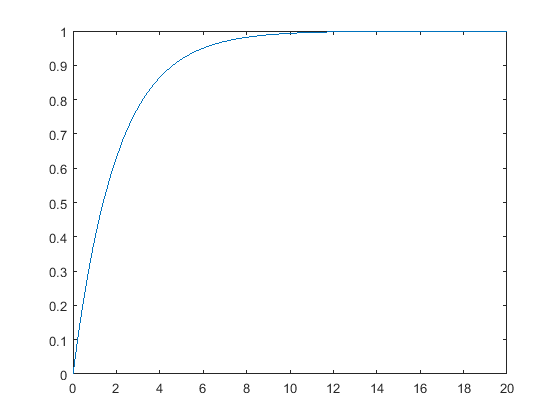

syms t 
assume(t>0)
fplot(1-exp(-t/2),[0 20])

Matrix inverse

syms A
A=[x x^2; 0 3]

$$A = \left(\begin{array}{cc} x & x^{2}\\ 0 & 3 \end{array}\right)$$

B=inv(A)

$$B = \left(\begin{array}{cc} \frac{1}{x} & -\frac{x}{3}\\ 0 & \frac{1}{3} \end{array}\right)$$

subs(B,x,2)

$$ans = \left(\begin{array}{cc} \frac{1}{2} & -\frac{2}{3}\\ 0 & \frac{1}{3} \end{array}\right)$$